% 3)
clear, clc, close all;

load handel; % the signal is in y and sampling freq in Fs
sound(y,Fs); pause(10); % Play the original sound
alpha = 0.9; D = 4196; % Echo parameters
b = [1,zeros(1,D),alpha]; % Filter parameters
x = filter(b,1,y); % Generate sound plus its echo
sound(x,Fs); % Play sound with echo

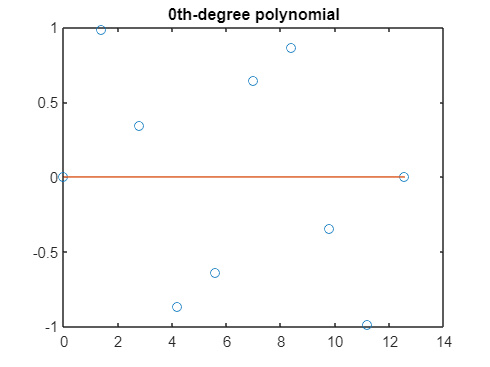

% 4)
clear, clc, close all;

x = linspace(0, 4*pi, 10);
y = sin(x);
x1 = linspace(0,4*pi);
% plot(x, y);

p1 = polyfit(x,y,0);
y1 = polyval(p1,x1);
plot(x,y,'o')
hold on
plot(x1,y1)
title('0th-degree polynomial')
hold off

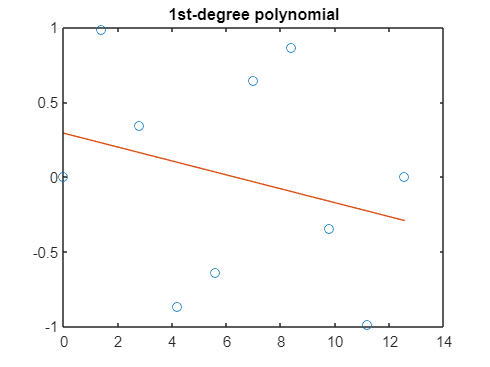


p2 = polyfit(x,y,1);
y2 = polyval(p2,x1);
plot(x,y,'o')
hold on
plot(x1,y2)
title('1st-degree polynomial')
hold off

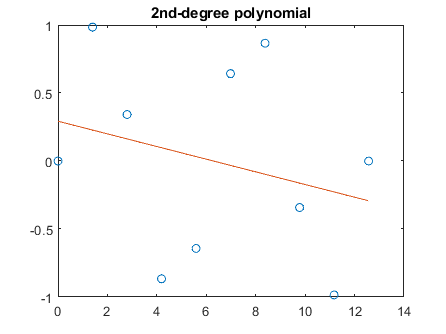


p3 = polyfit(x,y,2);
y3 = polyval(p3,x1);
plot(x,y,'o')
hold on
plot(x1,y3)
title('2nd-degree polynomial')
hold off

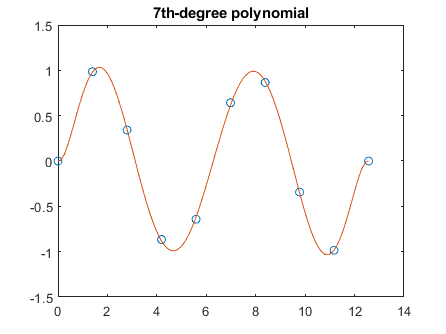


p4 = polyfit(x,y,7);
y4 = polyval(p4,x1);
plot(x,y,'o')
hold on
plot(x1,y4)
title('7th-degree polynomial')
hold off

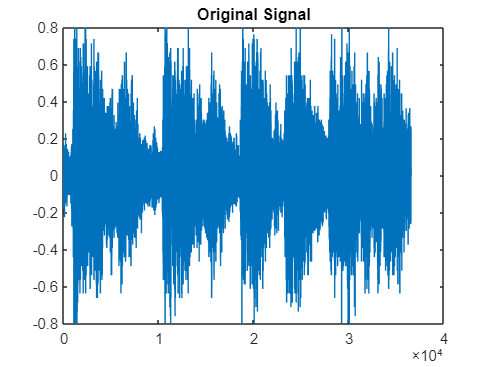

% 5)
clear, clc, close all;

load Signal_undersampled.mat 
a = Signal_undersampled;
Fs = 8192;
chunksize = floor(length(a)/18000);
% initalize y
y = [];
for index = 1:(floor( length(a) / chunksize)) - 1
    p = polyfit(1:chunksize, a(index*chunksize:(index*chunksize)+chunksize-1), 1);
    % Add new values to y without erasing existing values
    y = [y, polyval(p, 1:chunksize*2)];
end
plot(a); title('Original Signal')

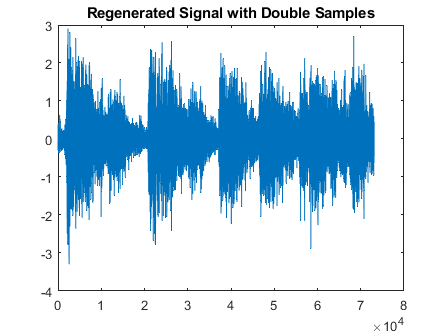

plot(y); title('Regenerated Signal with Double Samples')

% This commented out code adjusts the amplitude of regenerated signal to
% better match the original signal
% Coefficient = max(a)/max(y);
% y = y*Coefficient;
% plot(y); title('Regenerated Signal with Double Samples and Adjusted Amplitude')
sound(a,Fs);pause(5);
sound(y,Fs); 
% Save the file
% audiowrite('Regenerated Signal.wav',y,Fs)


